Computes the balance resistor across each capacitor in a capacitor bank.

Computes the balance resistor based on the following source material:

[Source: CDM Cornell Dubilier, "Aluminum Electrolytic Capacitor Application Guide"](https://www.rellpower.com/wp/wp-content/uploads/2018/09/AEappGUIDE1.pdf)

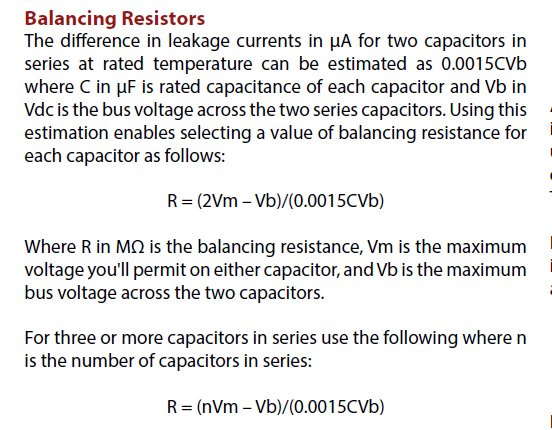

Vmax: max voltage allowed across each capacitor, V

Vbus: Max voltage across the entire series combination, V

C: Rated capacitance of each capacitor, F

n: Number of capacitors in series

R: Balance resistor value, Ohms

function R = computeBalanceResistor(Vmax, Vbus, C, n)
C_uf = C*1e6;   % Convert to uF
R = ((n*Vmax-Vbus)/(0.0015*C_uf*Vbus))*1e6;    % Compute balance resistor, convert to Ohm

end